% syms l n k

% eqn = l == n^2 + 5*k - 4*(n - 6 + 4*n);

% x1_deriv = diff(x1);
% x1_int = int(x1);
% eqn_sn = solve(eqn, n);
% eqn_full = expand(eqn);

% disp(x1_deriv);
% disp(x1_int);
% disp(eqn_sn);
% disp(eqn_full);

x = 4;
y = 6;
f = @(x, y) x^2 + 5*x - sin(y);
result = f(x,y);
fprintf('f value is %f\n', result);

f value is 36.279415



% Numerical calculations with anonymus function @ 
f1 = @(x) x^2-sin(x);
result1 = f1(2);
disp(result1);

    3.0907




% integral(@(x) f(x), A, b)
f2 = @(z) z*2 - exp(z) + sin(z);
res = integral(f2, 0, 6);
disp(res);

 -366.3890



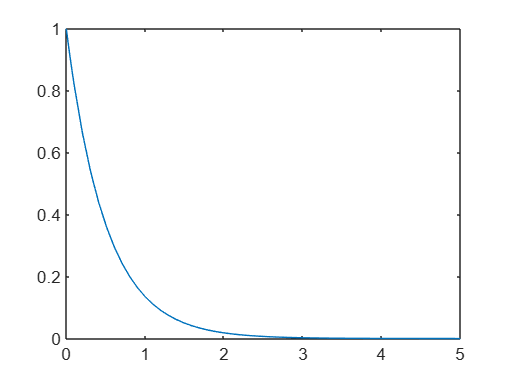


% Solving for numerical calculations of  ordinary differential equations by Runge- Kutta 4-5 methods  
f = @(t, y) -2*y;
tspan = [0, 5];
y0 = 1;

[t, y] = ode45(f, tspan, y0);


plot(t, y);

xlabel('Time', t);

Error using xyzlabel (line 4)
Incorrect number of inputs for property-value pairs.

Error in xlabel (line 7)
    xyzlabel("XLabel", varargin);

ylabel('Distance', y);
title('Using ODE45 function to solve de');
grid on;




